## simple Bi-phase Materials

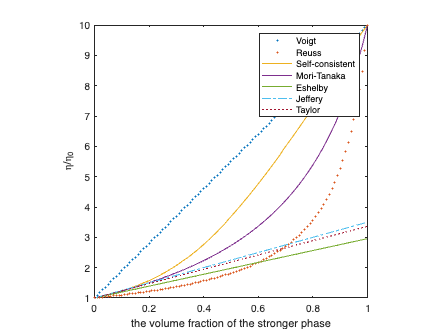


% viscosity ratio
  r = 10;
% volume fraction of the stronger phase  
  phi=0:0.01:1; 
% Voigt 
  etaV=phi.*r+(1-phi);
% Ruess
  etaR=(phi./r+(1-phi)).^-1;
% Eshelby
  etaE = 1 + 5.*phi.*(r-1)./(2*r+3);
% Mori-Tanaka  
  etaMT=((2+3.*phi).*r+1-phi)./(2.*(1-phi).*r+1+4.*phi);
% Self-Consistent   
  etaSC=zeros(size(phi));

  for jj=1:numel(phi)

      etaSC_0=etaV(jj);

      for kk=1:1000
          etaSC_new = 1+5.*phi(jj).*(r-1).*etaSC_0/(2*r+3*etaSC_0);
          err = abs(etaSC_new/etaSC_0 -1);
          etaSC_0 = etaSC_new;
          if err<=0.01
             break
          end
      end
      etaSC(jj)=etaSC_new;
  end
% Jeffery (1922), Einstein's result
  etaJ = 1+2.5.*phi;
% Taylor(1932)
  etaT=1+(5*r+2)/(2*(r+1)).*phi;
% Plot  
  figure('Name','Simple Bi-phase Results')
  plot(phi,etaV,'.',phi,etaR,'.',phi,etaSC,'-',phi,etaMT,'-',...
      phi,etaE,'-',phi,etaJ,'-.',phi,etaT,':')
  xlim([0 1])
  ylim([1,r])
  axis square
  xlabel('the volume fraction of the stronger phase')
  ylabel('\eta/\eta_0')
  legend('Voigt','Reuss','Self-consistent','Mori-Tanaka',...
        'Eshelby','Jeffery','Taylor')